### Μέρος A2

#### Η πηγή 

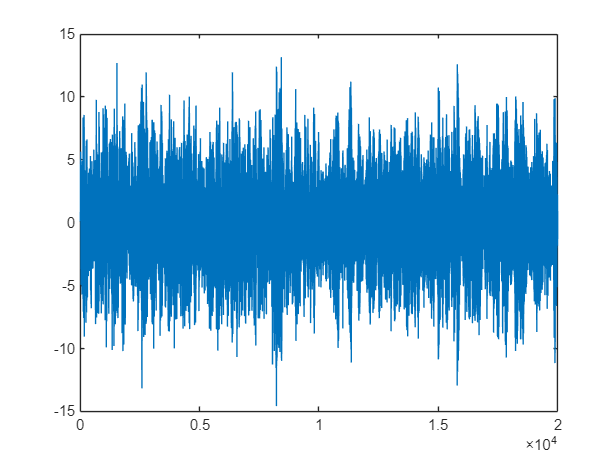

load source.mat;
plot(t)

%sound(t); %Δεν ακούγεται κάτι ευχάριστο ή κατανοήσιμο. 

**Υπολογισμός Στοχαστικών Ποσοτήτων**

p=5;
[R,r] = Rx(p,t)

R =    12.4251    5.5417   -4.5025   -5.1474   -0.8877
    5.5417   12.4251    5.5416   -4.5024   -5.1473
   -4.5025    5.5416   12.4250    5.5416   -4.5023
   -5.1474   -4.5024    5.5416   12.4250    5.5416
   -0.8877   -5.1473   -4.5023    5.5416   12.4250


r =     5.5415
   -4.5025
   -5.1477
   -0.8879
   -0.7998


**Υπολογισμός και Κβάντιση Συντελεστών Φίλτρου Πρόβλεψης**

a = R\r

a =     1.2852
   -1.5856
    0.9901
   -0.5424
   -0.0287


[a_quantised_areas, a_centers] = iquantizer(a, 8, -2, 2);

a_quantised = a_centers(a_quantised_areas)

a_quantised =     1.2988
   -1.5723
    0.9980
   -0.5332
   -0.0410


#### 1.Κωδικοποίηση και Αποκωδικοποίηση

Σταθερές

N = 4;
min_value = -3.5;
max_value = 3.5;

**Η κωδικοποίηση**

[encoded, centers, a, y] = idpcm_enco(t, p, N, min_value, max_value)

encoded =      7
     8
     9
     4
     2
     9
     1
     1
     5
     1


centers =     3.2812
    2.8438
    2.4062
    1.9688
    1.5312
    1.0938
    0.6562
    0.2188
   -0.2188
   -0.6562


a =     1.2988
   -1.5723
    0.9980
   -0.5332
   -0.0410


y =     0.8147
    0.0534
   -0.2324
    1.7598
    2.7576
   -0.2853
    3.7410
    3.1180
    1.3783
    3.4059


Σημείωση : Είναι προφανές ότι θα μπορούσαμε να χρησιμοποιούμε την Rx καθώς και να παράγουμε τα κέντρα των κβαντισμένων περιοχών έξω από την συνάρτηση κωδικοποίησης. Ο μόνος λόγος που προτιμήσαμε να υπολογίζονται όλα εντός της, είναι για να διευκολυνθούμε στα επόμενα ερωτήματα με τις πολλαπλές επαναλήψεις κωδικοποιήσεων με διαφορετικές παραμέτρους.

**Η αποκωδικοποίηση**

reconstructed = idpcm_deco(encoded, a, centers)

reconstructed =     0.6562    1.0711    0.1406    1.1223    4.7994    3.7926    1.6625    3.6633    4.8556    3.2682    1.1935    0.7675    2.9242    5.1219    4.0192    2.4713    1.5055    2.5115    4.2896    4.0489    2.0857    2.5046    3.5933    2.4447    0.2785    0.6519    1.4864   -0.4861   -3.2228   -5.1408   -1.8207    1.6060   -0.8502   -2.7919   -1.9112    0.0583   -0.4120   -2.1046   -1.1126   -0.0313   -0.3933   -1.5267   -0.4975    2.0803    3.2651    0.2100   -1.8006   -0.7176    0.0635   -1.4885


t'

ans =     0.8147    0.9058    0.1270    0.9134    4.7133    3.7260    2.1223    3.5001    4.7026    3.3928    0.9893    0.7583    3.7443    5.6527    4.2262    2.3023    1.3288    2.4903    4.5989    4.0344    2.2921    2.6377    3.4092    2.5934    0.1552    0.5054    1.4496   -0.4271   -3.0529   -4.9416   -1.7834    1.7727   -0.6652   -2.9294   -2.0644    0.1224   -0.3023   -1.9171   -1.1175    0.0946   -0.4482   -1.7144   -0.6236    2.2635    3.2661    0.0121   -1.9296   -0.6260   -0.0365   -1.4735


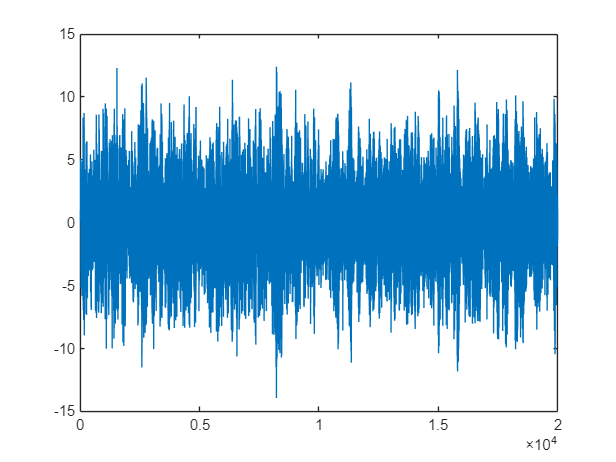

plot(reconstructed);

#### 2.Πως Επηρεάζουν οι Παράμετροι p και N το Σφάλμα Πρόβλεψης;

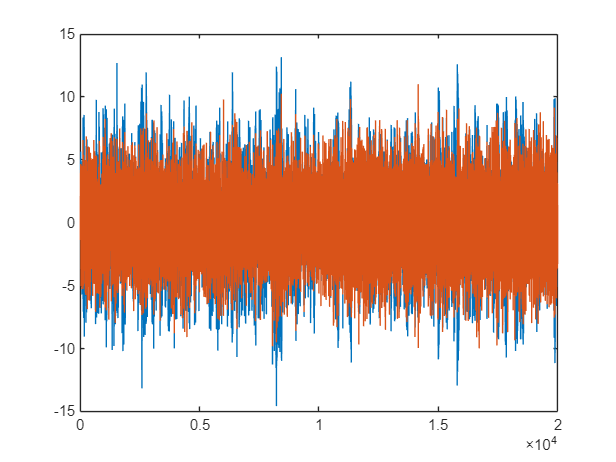

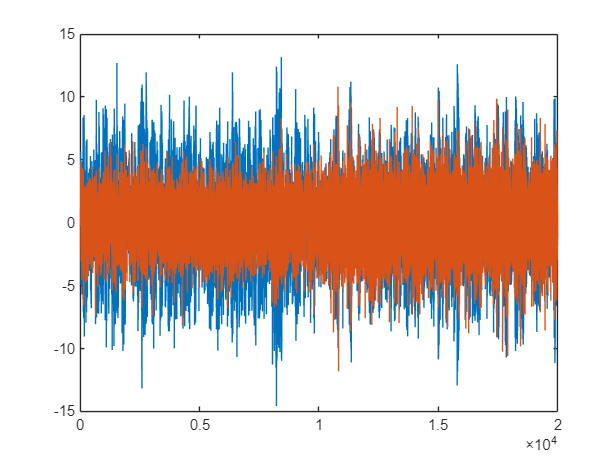

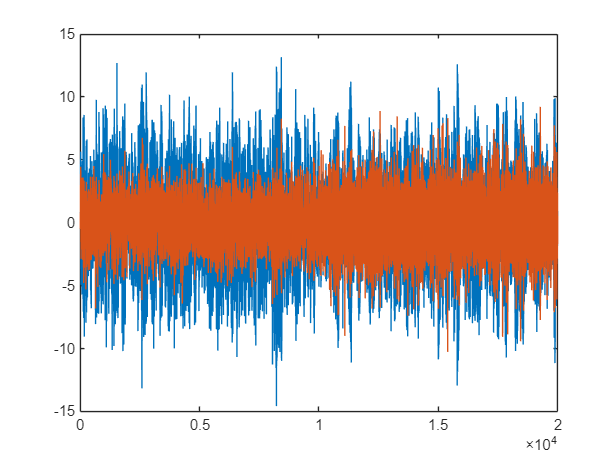

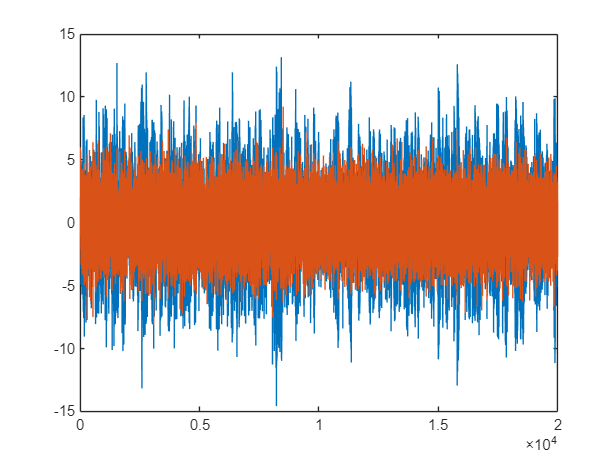

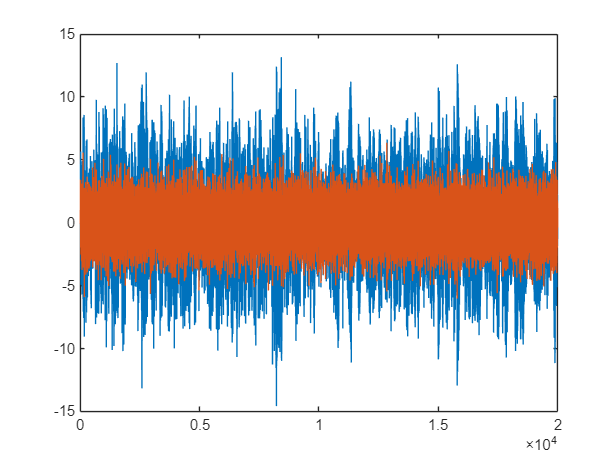

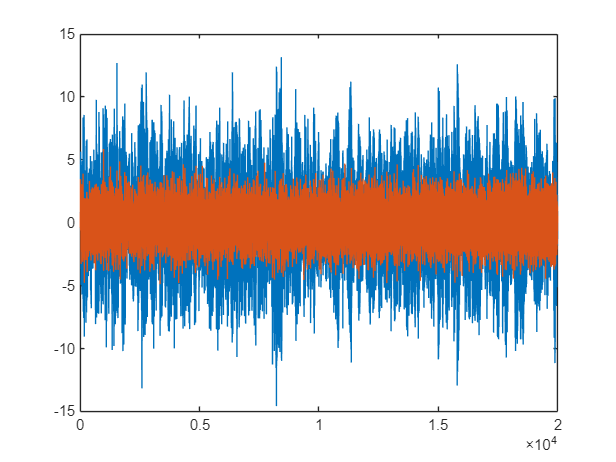

for p = [5,10]
    for N = 1:3
        [encoded, centers, a, y] = idpcm_enco(t, p, N, min_value, max_value);
        figure;
        plot(t);
        hold on
        plot(y);
        hold off
    end
end

#### 3.Πως Επηρεάζουν οι Παράμετροι p και N το Μέσο Τετραγωνικό Σφάλμα Πρόβλεψης;

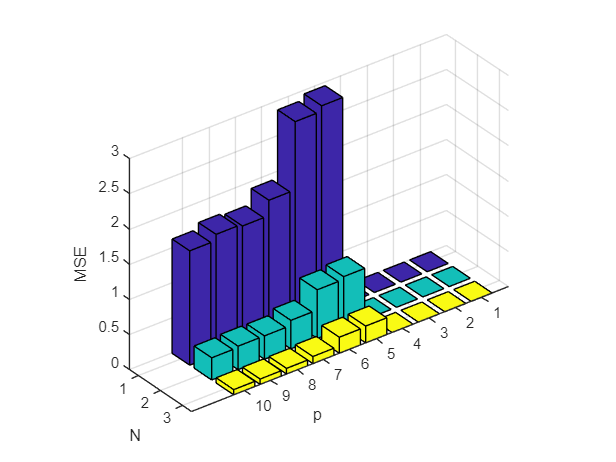

for p = 5:10
    for N = 1:3
        [encoded, centers, a, y] = idpcm_enco(t, p, N, min_value, max_value);
        reconstructed = idpcm_deco(encoded, a, centers);
        MSE(p,N) = 1/size(reconstructed,2) * sum((t-reconstructed').^2);

    end
end
bar3(MSE);
xlabel('N');
ylabel('p');
zlabel('MSE');
view([52.59 30.95])

#### 4.Επανακατασκευή του Σήματος

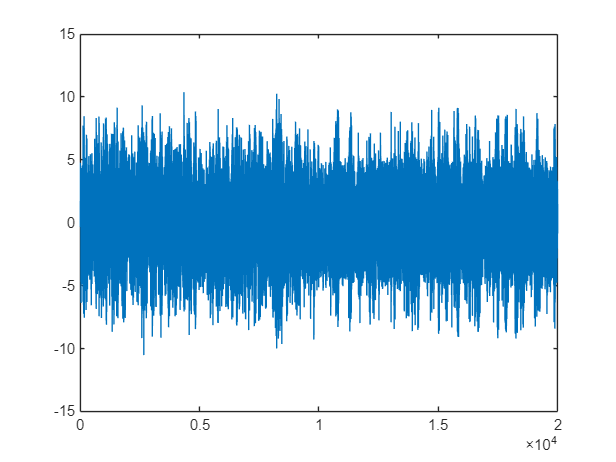

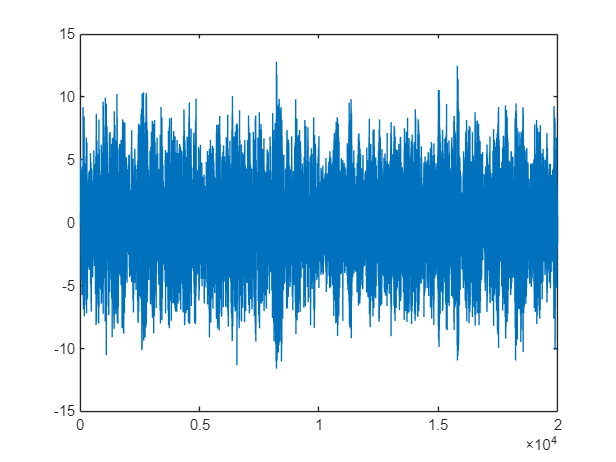

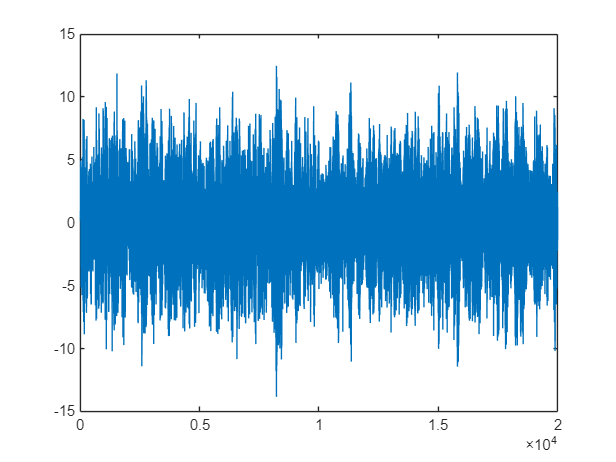

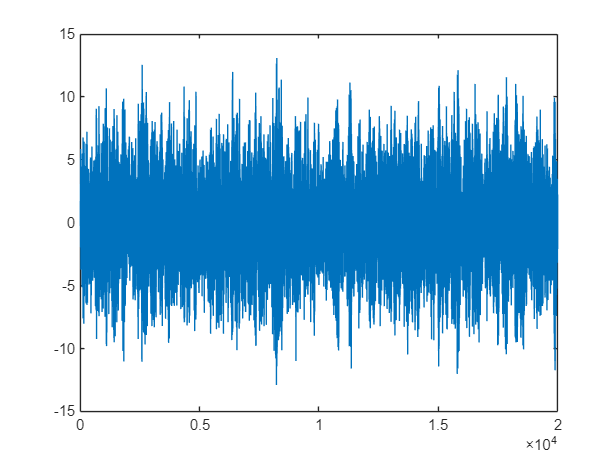

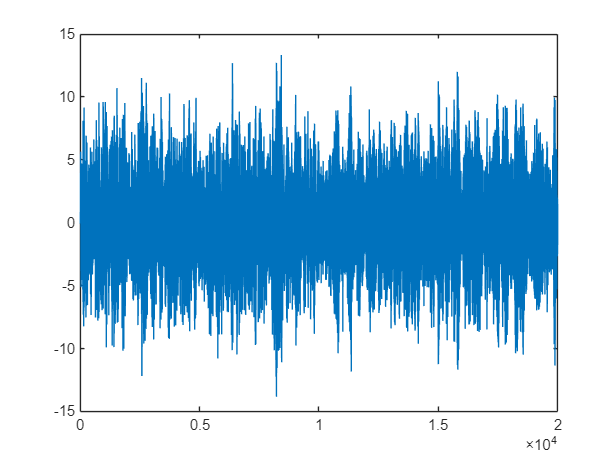

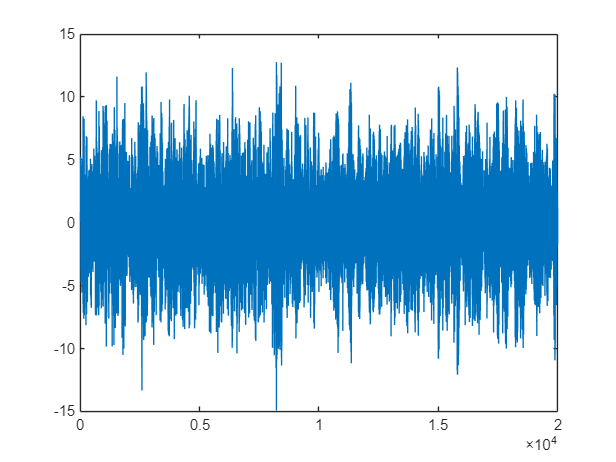

for p = [5,10]
    for N = 1:3
        [encoded, centers, a, y] = idpcm_enco(t, p, N, min_value, max_value);
        reconstructed = idpcm_deco(encoded, a, centers);

        figure;
        plot(reconstructed);
    end
end

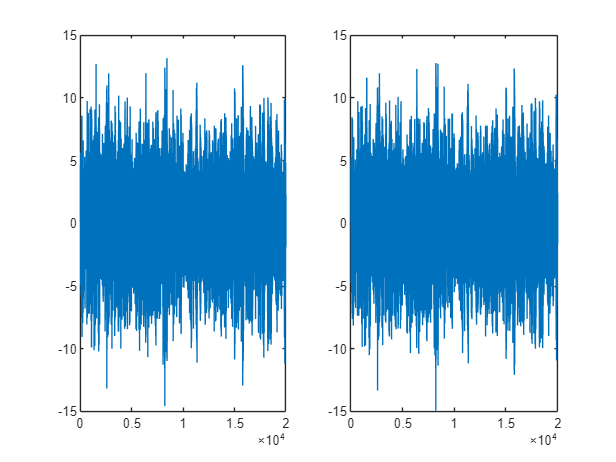

figure;
subplot(1,2,1);
plot(t);

subplot(1,2,2);
plot(reconstructed);

**Τέλος Άσκησης**

Μόλις τελειώσετε το παιχνίδι, μην ξεχάσετε να εκτελέσετε τα ακόλουθα:

rmpath './functions'

rmpath './sources'